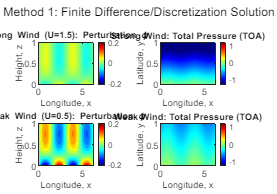

clear; clc; close all;

Nz = 100;               
Lz = 1.0;               
z = linspace(0, Lz, Nz)'; 
dz = z(2) - z(1);

Nx = 100;               
x = linspace(0, 2*pi, Nx);

Ny = 50;
y = linspace(0, 1, Ny);
[X_mesh, Y_mesh] = meshgrid(x, y);

% Physical Parameters 
H = 0.5;                
beta_L = 1.0;           
S = 1.0;                
ks = 2.0;               
Q0 = 1.0;               

%Threshold Wind
U_th = 4 * H^2 * beta_L * S;

% Density weighting for visualization (from paper)
density_weight = exp(-z / (2*H)); 

% ----------------- SET UP -----------------

% Wind Speeds
U_strong = 1.5;
U_weak = 0.5;

% Method 1: Finite Difference
Phi_FD_S = zeros(Nz, Nx);
Phi_FD_W = zeros(Nz, Nx);

% Method 2: Analytical
Phi_AN_S = zeros(Nz, Nx);
Phi_AN_W = zeros(Nz, Nx);

% Method 3: BVP4C
Phi_BVP_S = zeros(Nz, Nx);
Phi_BVP_W = zeros(Nz, Nx);

solinit = bvpinit(z, [0 0]); % Guess for BVP

for i = 1:Nx
    Fx = sin(2*x(i)) / 2;
    
    % Finite Difference ---

    Phi_FD_S(:, i) = solve_fd(U_strong, Fx, H, beta_L, S, ks, Q0, z, dz, Nz);
    Phi_FD_W(:, i) = solve_fd(U_weak, Fx, H, beta_L, S, ks, Q0, z, dz, Nz);
    
    % Analytical ---

    Phi_AN_S(:, i) = solve_analytic(U_strong, Fx, H, beta_L, S, ks, Q0, z);
    Phi_AN_W(:, i) = solve_analytic(U_weak, Fx, H, beta_L, S, ks, Q0, z);
     
    % BVP4C ---

    % PDE, Strong wind
    ode_S = @(z,y) pde_sys(z, y, U_strong, Fx, H, beta_L, S, ks, Q0);
    bc_S = @(ya,yb) pde_bc(ya, yb, U_strong, Fx, H, beta_L, S, ks, Q0);
    sol_S = bvp4c(ode_S, bc_S, solinit);
    Phi_BVP_S(:, i) = deval(sol_S, z, 1);
    
    % PDE, Weak wind
    ode_W = @(z,y) pde_sys(z, y, U_weak, Fx, H, beta_L, S, ks, Q0);
    bc_W = @(ya,yb) pde_bc(ya, yb, U_weak, Fx, H, beta_L, S, ks, Q0);
    sol_W = bvp4c(ode_W, bc_W, solinit);
    Phi_BVP_W(:, i) = deval(sol_W, z, 1);
end

% Apply density weighting 
W_FD_S = Phi_FD_S .* density_weight;
W_FD_W = Phi_FD_W .* density_weight;

W_AN_S = Phi_AN_S .* density_weight;
W_AN_W = Phi_AN_W .* density_weight;

W_BVP_S = Phi_BVP_S .* density_weight;
W_BVP_W = Phi_BVP_W .* density_weight;

% Method 1 Pressure
Pres_FD_S = -U_strong * Y_mesh + repmat(W_FD_S(end,:), Ny, 1);
Pres_FD_W = -U_weak * Y_mesh + repmat(W_FD_W(end,:), Ny, 1);

% Method 2 Pressure
Pres_AN_S = -U_strong * Y_mesh + repmat(W_AN_S(end,:), Ny, 1);
Pres_AN_W = -U_weak * Y_mesh + repmat(W_AN_W(end,:), Ny, 1);

% Method 3 Pressure
Pres_BVP_S = -U_strong * Y_mesh + repmat(W_BVP_S(end,:), Ny, 1);
Pres_BVP_W = -U_weak * Y_mesh + repmat(W_BVP_W(end,:), Ny, 1);

% ----------------- VISUALIZATION -----------------

max_phi = max(abs(W_FD_W(:))); 
clim_phi = [-max_phi, max_phi]; 

max_p = max(max(abs(Pres_FD_S(:))), max(abs(Pres_FD_W(:))));
clim_p = [-max_p, max_p] * 0.8; 

% --- METHOD 1 FIGURES ---
figure('Position', [100, 100, 1000, 700], 'Name', 'Method 1: Finite Difference');
% Strong - Perturbation
subplot(2,2,1);
contourf(x, z, W_FD_S, 20, 'LineColor', 'none');
clim(clim_phi);
colorbar;
colormap(jet);
title(['Strong Wind (U=', num2str(U_strong), '): Perturbation \phi']);
ylabel('Height, z');
xlabel('Longitude, x');

% Strong - Pressure
subplot(2,2,2);
contourf(X_mesh, Y_mesh, Pres_FD_S, 20, 'LineColor', 'none');
clim(clim_p);
colorbar;
title('Strong Wind: Total Pressure (TOA)');
ylabel('Latitude, y');
xlabel('Longitude, x');

% Weak - Perturbation
subplot(2,2,3);
contourf(x, z, W_FD_W, 20, 'LineColor', 'none');
clim(clim_phi);
colorbar;
title(['Weak Wind (U=', num2str(U_weak), '): Perturbation \phi']);
ylabel('Height, z');
xlabel('Longitude, x');

% Weak - Pressure
subplot(2,2,4);
contourf(X_mesh, Y_mesh, Pres_FD_W, 20, 'LineColor', 'none');
clim(clim_p);
colorbar;
title('Weak Wind: Total Pressure (TOA)');
ylabel('Latitude, y');
xlabel('Longitude, x');
sgtitle('Method 1: Finite Difference/Discretization Solution');

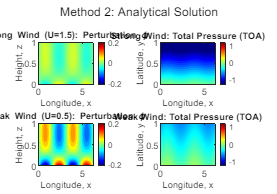



% --- METHOD 2 FIGURES ---
figure('Position', [150, 150, 1000, 700], 'Name', 'Method 2: Analytical');
% Strong - Perturbation
subplot(2,2,1);
contourf(x, z, W_AN_S, 20, 'LineColor', 'none');
clim(clim_phi);
colorbar;
colormap(jet);
title(['Strong Wind (U=', num2str(U_strong), '): Perturbation \phi']);
ylabel('Height, z');
xlabel('Longitude, x');

% Strong - Pressure
subplot(2,2,2);
contourf(X_mesh, Y_mesh, Pres_AN_S, 20, 'LineColor', 'none');
clim(clim_p);
colorbar;
title('Strong Wind: Total Pressure (TOA)');
ylabel('Latitude, y');
xlabel('Longitude, x');

% Weak - Perturbation
subplot(2,2,3);
contourf(x, z, W_AN_W, 20, 'LineColor', 'none');
clim(clim_phi);
colorbar;
title(['Weak Wind (U=', num2str(U_weak), '): Perturbation \phi']);
ylabel('Height, z');
xlabel('Longitude, x');

% Weak - Pressure
subplot(2,2,4);
contourf(X_mesh, Y_mesh, Pres_AN_W, 20, 'LineColor', 'none');
clim(clim_p);
colorbar;
title('Weak Wind: Total Pressure (TOA)');
ylabel('Latitude, y');
xlabel('Longitude, x');

sgtitle('Method 2: Analytical Solution');

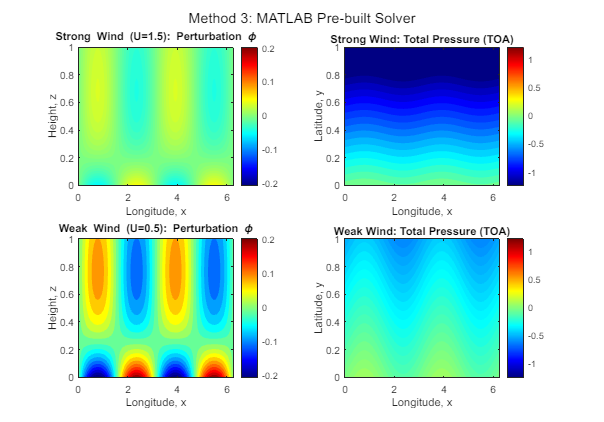



% --- METHOD 3 FIGURES ---
figure('Position', [200, 200, 1000, 700], 'Name', 'Method 3: BVP4C');
% Strong - Perturbation
subplot(2,2,1);
contourf(x, z, W_BVP_S, 20, 'LineColor', 'none');
clim(clim_phi);
colorbar;
colormap(jet);
title(['Strong Wind (U=', num2str(U_strong), '): Perturbation \phi']);
ylabel('Height, z');
xlabel('Longitude, x');

% Strong - Pressure
subplot(2,2,2);
contourf(X_mesh, Y_mesh, Pres_BVP_S, 20, 'LineColor', 'none');
clim(clim_p);
colorbar;
title('Strong Wind: Total Pressure (TOA)');
ylabel('Latitude, y');
xlabel('Longitude, x');

% Weak - Perturbation
subplot(2,2,3);
contourf(x, z, W_BVP_W, 20, 'LineColor', 'none');
clim(clim_phi); colorbar;
title(['Weak Wind (U=', num2str(U_weak), '): Perturbation \phi']);
ylabel('Height, z');
xlabel('Longitude, x');

% Weak - Pressure
subplot(2,2,4);
contourf(X_mesh, Y_mesh, Pres_BVP_W, 20, 'LineColor', 'none');
clim(clim_p); colorbar;
title('Weak Wind: Total Pressure (TOA)');
ylabel('Latitude, y');
xlabel('Longitude, x');

sgtitle('Method 3: MATLAB Pre-built Solver');

function phi = solve_fd(U, val_Fx, H, beta_L, S, ks, Q0, z, dz, Nz)
    
    c1 = (1/dz^2) + (1/(2*H*dz));   % Lower diag
    c2 = (-2/dz^2) + (beta_L*S/U);  % Main diag
    c3 = (1/dz^2) - (1/(2*H*dz));   % Upper diag
  
    e = ones(Nz, 1);
    A = spdiags([c1*e, c2*e, c3*e], -1:1, Nz, Nz);
    
    % Neumann
    A(1,1) = -1; A(1,2) = 1; 
    A(Nz,Nz) = 1; A(Nz,Nz-1) = -1;
    
    % RHS
    forcing_term = -(ks + 1/H) * (Q0/U) * val_Fx;
    RHS = forcing_term * exp(-ks * z);
     
    surface_slope = (Q0/U) * val_Fx;
    RHS(1) = surface_slope * dz;
    RHS(Nz) = 0; 
    
    phi = A \ RHS;
end

function phi = solve_analytic(U, val_Fx, H, beta_L, S, ks, Q0, z)
    delta = 1/(2*H);
    D_discriminant = delta^2 - (beta_L * S / U);
    K = ks + 1/H;
    RHS_Mag = -K * (Q0/U) * val_Fx;
    Char_Poly_ks = ks^2 + (1/H)*ks + (beta_L*S/U);
    C_part = RHS_Mag / Char_Poly_ks;
    
    dphi_dz_0 = (Q0/U) * val_Fx;
    dphi_dz_L = 0; 
    
    if D_discriminant > 0 % Strong Wind
        q = sqrt(D_discriminant);
        r1 = delta + q;
        r2 = delta - q;
        A_mat = [r1, r2; r1*exp(r1*z(end)), r2*exp(r2*z(end))];
        B_vec = [dphi_dz_0 + ks*C_part; dphi_dz_L + ks*C_part*exp(-ks*z(end))];
        coeffs = A_mat \ B_vec;
        phi_h = coeffs(1)*exp(r1*z) + coeffs(2)*exp(r2*z);
    else % Weak Wind
        m = sqrt(-D_discriminant);
        A11 = delta; A12 = m;
        E = exp(delta*z(end));
        C = cos(m*z(end)); S_sin = sin(m*z(end));
        A21 = E * (delta*C - m*S_sin);
        A22 = E * (delta*S_sin + m*C);
        A_mat = [A11, A12; A21, A22];
        B_vec = [dphi_dz_0 + ks*C_part; dphi_dz_L + ks*C_part*exp(-ks*z(end))];
        coeffs = A_mat \ B_vec;
        phi_h = exp(delta*z) .* (coeffs(1)*cos(m*z) + coeffs(2)*sin(m*z));
    end
    phi = phi_h + C_part*exp(-ks*z);
end

function dydz = pde_sys(z, y, U, val_Fx, H, beta_L, S, ks, Q0)
    phi = y(1);
    dphi = y(2);
    forcing = -(ks + 1/H) * (Q0/U) * val_Fx * exp(-ks * z);
    d2phi = (1/H)*dphi - (beta_L*S/U)*phi + forcing;
    dydz = [dphi; d2phi];
end

function res = pde_bc(ya, yb, U, val_Fx, H, beta_L, S, ks, Q0)
    forcing_surf = (Q0/U) * val_Fx;
    res = [ya(2) - forcing_surf; yb(2) - 0];
end